# Noisy Signal

## Note that this code is Mathworks code. I am posting it because some students could not access the last Matlab live script. 

## These FFT examples should be helpful in getting started with the fast finite fourier transform.

Use Fourier transforms to find the frequency components of a signal buried in noise.

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

Form a signal containing a 50 Hz sinusoid of amplitude 0.7 and a 120 Hz sinusoid of amplitude 1.

S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);

Corrupt the signal with zero-mean white noise with a variance of 4.

X = S + 2*randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal `X(t)`. 

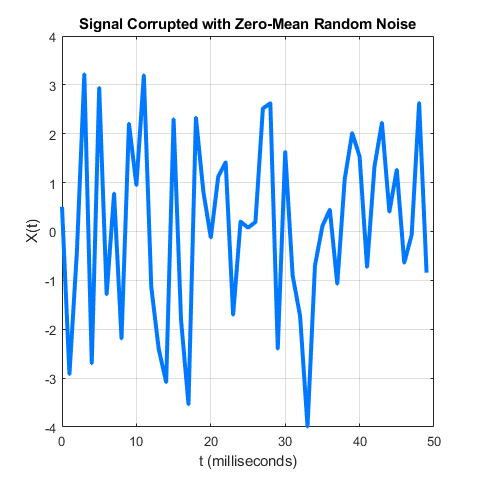

plot(1000*t(1:50),X(1:50))
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

Compute the Fourier transform of the signal. 

Y = fft(X);

Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length `L`.

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1`. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.

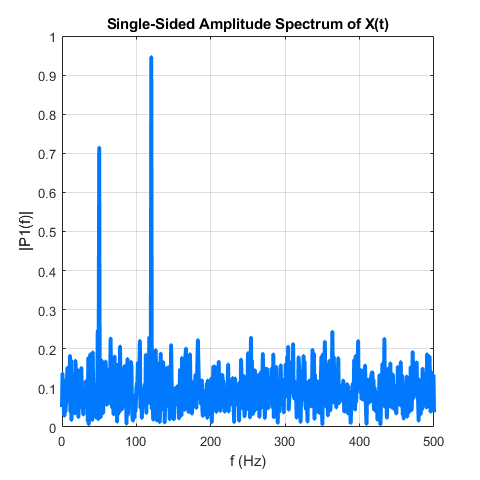

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Now, take the Fourier transform of the original, uncorrupted signal and retrieve the exact amplitudes, 0.7 and 1.0.

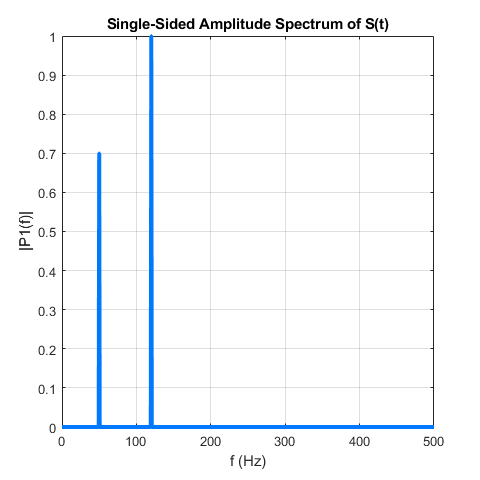

Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

# Gaussian Pulse

Convert a Gaussian pulse from the time domain to the frequency domain.

Define signal parameters and a Gaussian pulse, `X`.

Fs = 100;           % Sampling frequency
t = -0.5:1/Fs:0.5;  % Time vector 
L = length(t);      % Signal length

X = 1/(4*sqrt(2*pi*0.01))*(exp(-t.^2/(2*0.01)));

Plot the pulse in the time domain.

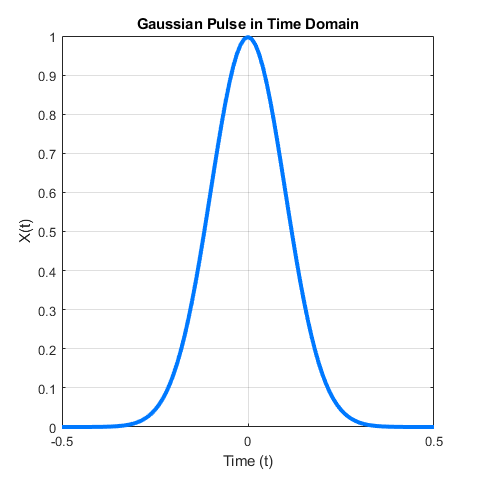

plot(t,X)
title('Gaussian Pulse in Time Domain')
xlabel('Time (t)')
ylabel('X(t)')

To use the `fft` function to convert the signal to the frequency domain, first identify a new input length that is the next power of 2 from the original signal length. This will pad the signal `X` with trailing zeros in order to improve the performance of `fft`.

n = 2^nextpow2(L);

Convert the Gaussian pulse to the frequency domain.

Y = fft(X,n);

Define the frequency domain and plot the unique frequencies.

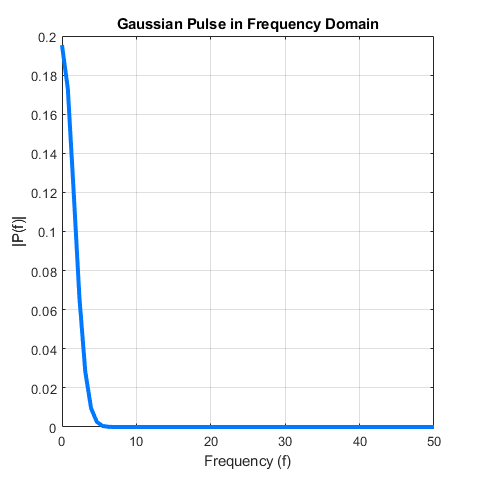

f = Fs*(0:(n/2))/n;
P = abs(Y/n);

plot(f,P(1:n/2+1)) 
title('Gaussian Pulse in Frequency Domain')
xlabel('Frequency (f)')
ylabel('|P(f)|')

*Copyright 2015 The MathWorks, Inc.*

# Cosine Waves

Compare cosine waves in the time domain and the frequency domain.

Specify the parameters of a signal with a sampling frequency of 1kHz and a signal duration of 1 second.

Fs = 1000;                    % Sampling frequency
T = 1/Fs;                     % Sampling period
L = 1000;                     % Length of signal
t = (0:L-1)*T;                % Time vector

Create a matrix where each row represents a cosine wave with scaled frequency. The result, `X`, is a 3-by-1000 matrix. The first row has a wave frequency of 50, the second row has a wave frequency of 150, and the third row has a wave frequency of 300.

x1 = cos(2*pi*50*t);          % First row wave
x2 = cos(2*pi*150*t);         % Second row wave
x3 = cos(2*pi*300*t);         % Third row wave

X = [x1; x2; x3];

Plot the first 100 entries from each row of `X` in a single figure in order and compare their frequencies.

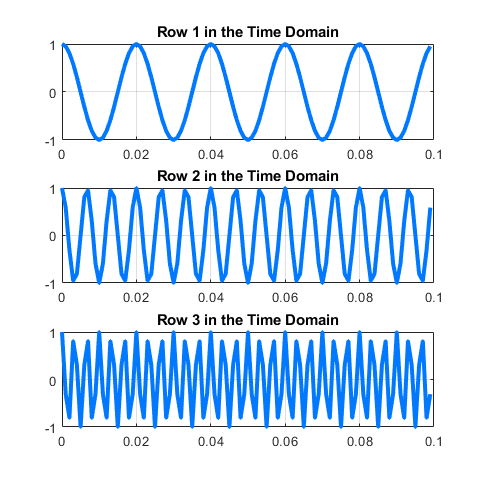

for i = 1:3
    subplot(3,1,i)
    plot(t(1:100),X(i,1:100))
    title(['Row ',num2str(i),' in the Time Domain'])
end

For algorithm performance purposes, `fft` allows you to pad the input with trailing zeros. In this case, pad each row of `X` with zeros so that the length of each row is the next higher power of 2 from the current length. Define the new length using the `nextpow2` function.

n = 2^nextpow2(L);

Specify the `dim` argument to use `fft` along the rows of `X`, that is, for each signal.

dim = 2;

Compute the Fourier transform of the signals.

Y = fft(X,n,dim);

Calculate the double-sided spectrum and single-sided spectrum of each signal.

P2 = abs(Y/n);
P1 = P2(:,1:n/2+1);
P1(:,2:end-1) = 2*P1(:,2:end-1);

In the frequency domain, plot the single-sided amplitude spectrum for each row in a single figure.

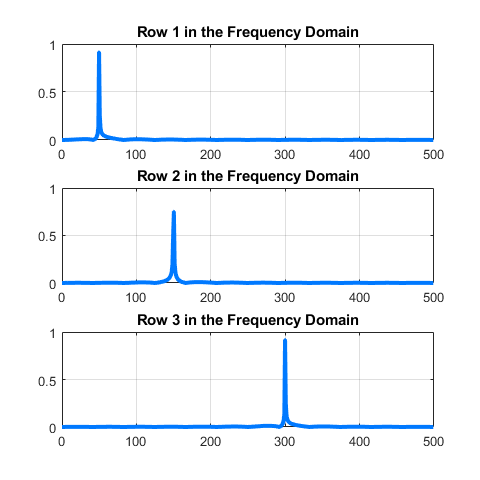

for i=1:3
    subplot(3,1,i)
    plot(0:(Fs/n):(Fs/2-Fs/n),P1(i,1:n/2))
    title(['Row ',num2str(i), ' in the Frequency Domain'])
end

*Copyright 2015 The MathWorks, Inc.*